# **Extended Estimator Approach**

The tests are done on the same four sampling times. When we change $T_{\mathrm{rs}}$ we have to evaluate again the matrix $A$ and the ones thta derive from it (this matrix is not defined in 'parametres.mlx'). Hence it is also necessary to evaluate again pole allocation only for the observe. Moreover in the first part of the file we perfom simulations at different step seizes (30°, 60, 90°) changing $T_{\mathrm{rs}}$. In the second part we do point 7 and 8 of the assignemnt

clear all
load('parameters.mat');

#### Observer for Trs = 0.15s

ssError.ridx = 1;
ssError.freq = ssError.wrs(ssError.ridx);
               
%% Settings of the correct poles for the estimator
ssEstimator.A_rho = [0 1 0; 0 0 1; 0 -ssError.wrs(ssError.ridx)^2 0];
ssEstimator.Ae = [ssEstimator.A_rho, zeros(3,2); ssP.B*ssEstimator.C_rho, ssP.A];
ssEstimator.Le = (place(ssEstimator.Ae', ssEstimator.Ce', ssEstimator.obspoles))'; % notice the last transpose
ssEstimator.Le

ans = 1.0e+06 *

    0.0099
    0.1869
   -8.3825
    0.0002
    0.0209


SIMULATIONS

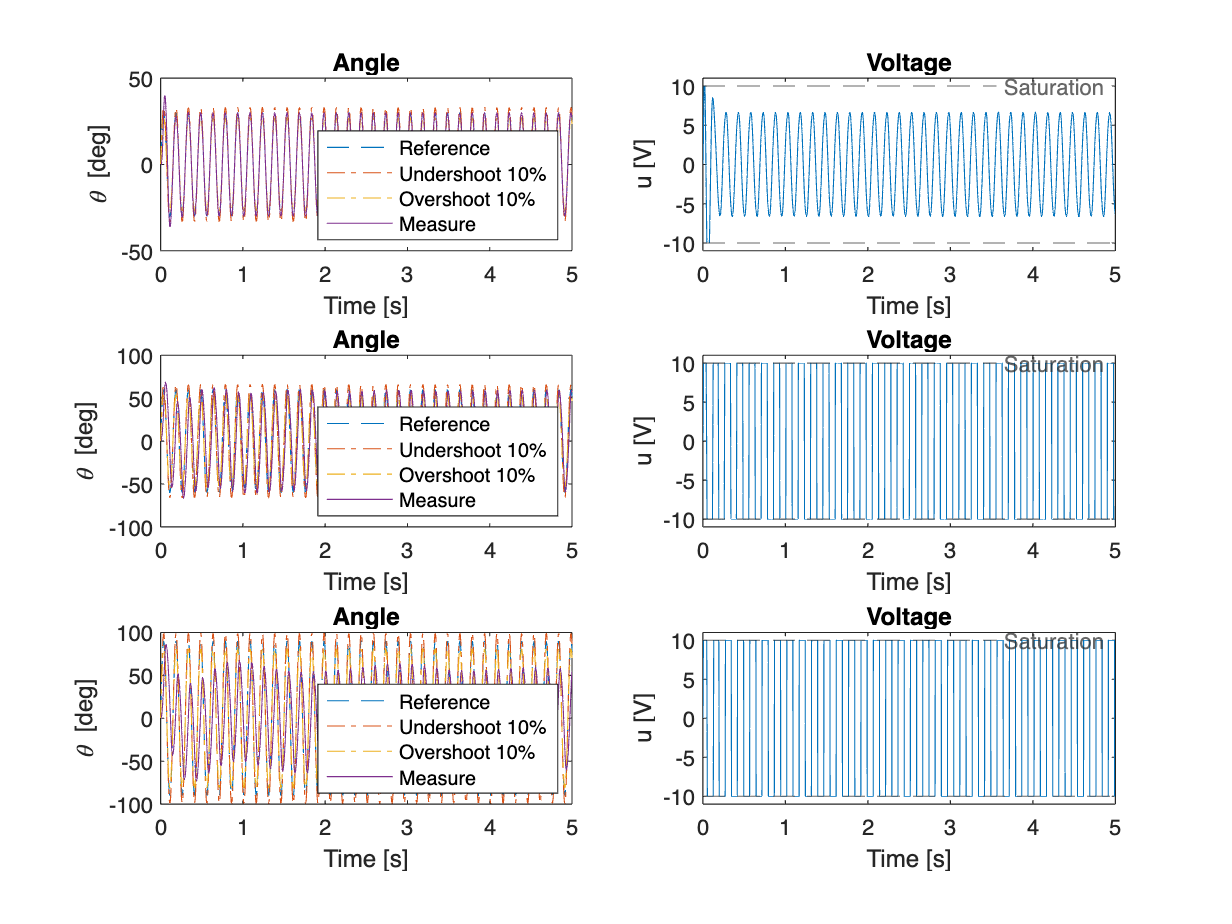

ssError.amp = 30;
ssObserver_simul.Tr1.amp30 =sim('lab1_extended_estimator','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');
ssError.amp = 60;
ssObserver_simul.Tr1.amp60 =sim('lab1_extended_estimator','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
ssError.amp = 90;
ssObserver_simul.Tr1.amp90 =sim('lab1_extended_estimator','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

figure("Name",'Results')
subplot(3,2,1)
plot(ssObserver_simul.Tr1.amp30.thref.time, ssObserver_simul.Tr1.amp30.thref.signals.values,'--');
hold on;
plot(ssObserver_simul.Tr1.amp30.thref.time, ssObserver_simul.Tr1.amp30.thref.signals.values*1.10,'-.');
plot(ssObserver_simul.Tr1.amp30.thref.time, ssObserver_simul.Tr1.amp30.thref.signals.values*0.9,'-.');
plot(ssObserver_simul.Tr1.amp30.thl_meas.time, ssObserver_simul.Tr1.amp30.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,2)
plot(ssObserver_simul.Tr1.amp30.u.time, ssObserver_simul.Tr1.amp30.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')


subplot(3,2,3)
plot(ssObserver_simul.Tr1.amp60.thref.time, ssObserver_simul.Tr1.amp60.thref.signals.values,'--');
hold on;
plot(ssObserver_simul.Tr1.amp60.thref.time, ssObserver_simul.Tr1.amp60.thref.signals.values*1.10,'-.');
plot(ssObserver_simul.Tr1.amp60.thref.time, ssObserver_simul.Tr1.amp60.thref.signals.values*0.9,'-.');
plot(ssObserver_simul.Tr1.amp60.thl_meas.time, ssObserver_simul.Tr1.amp60.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,4)
plot(ssObserver_simul.Tr1.amp60.u.time, ssObserver_simul.Tr1.amp60.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')


subplot(3,2,5)
plot(ssObserver_simul.Tr1.amp90.thref.time, ssObserver_simul.Tr1.amp90.thref.signals.values,'--');
hold on;
plot(ssObserver_simul.Tr1.amp90.thref.time, ssObserver_simul.Tr1.amp90.thref.signals.values*1.10,'-.');
plot(ssObserver_simul.Tr1.amp90.thref.time, ssObserver_simul.Tr1.amp90.thref.signals.values*0.9,'-.');
plot(ssObserver_simul.Tr1.amp90.thl_meas.time, ssObserver_simul.Tr1.amp90.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,6)
plot(ssObserver_simul.Tr1.amp90.u.time, ssObserver_simul.Tr1.amp90.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')

#### Observer for Trs = 0.25s

ssError.ridx = 2;
ssError.freq = ssError.wrs(ssError.ridx);
               
%% Settings of the correct poles for the estimator
ssEstimator.A_rho = [0 1 0; 0 0 1; 0 -ssError.wrs(ssError.ridx)^2 0];
ssEstimator.Ae = [ssEstimator.A_rho, zeros(3,2); ssP.B*ssEstimator.C_rho, ssP.A];
ssEstimator.Le = (place(ssEstimator.Ae', ssEstimator.Ce', ssEstimator.obspoles))'; % notice the last transpose
ssEstimator.Le

ans = 1.0e+06 *

    0.0117
    0.3812
    1.6166
    0.0002
    0.0221


SIMULATIONS

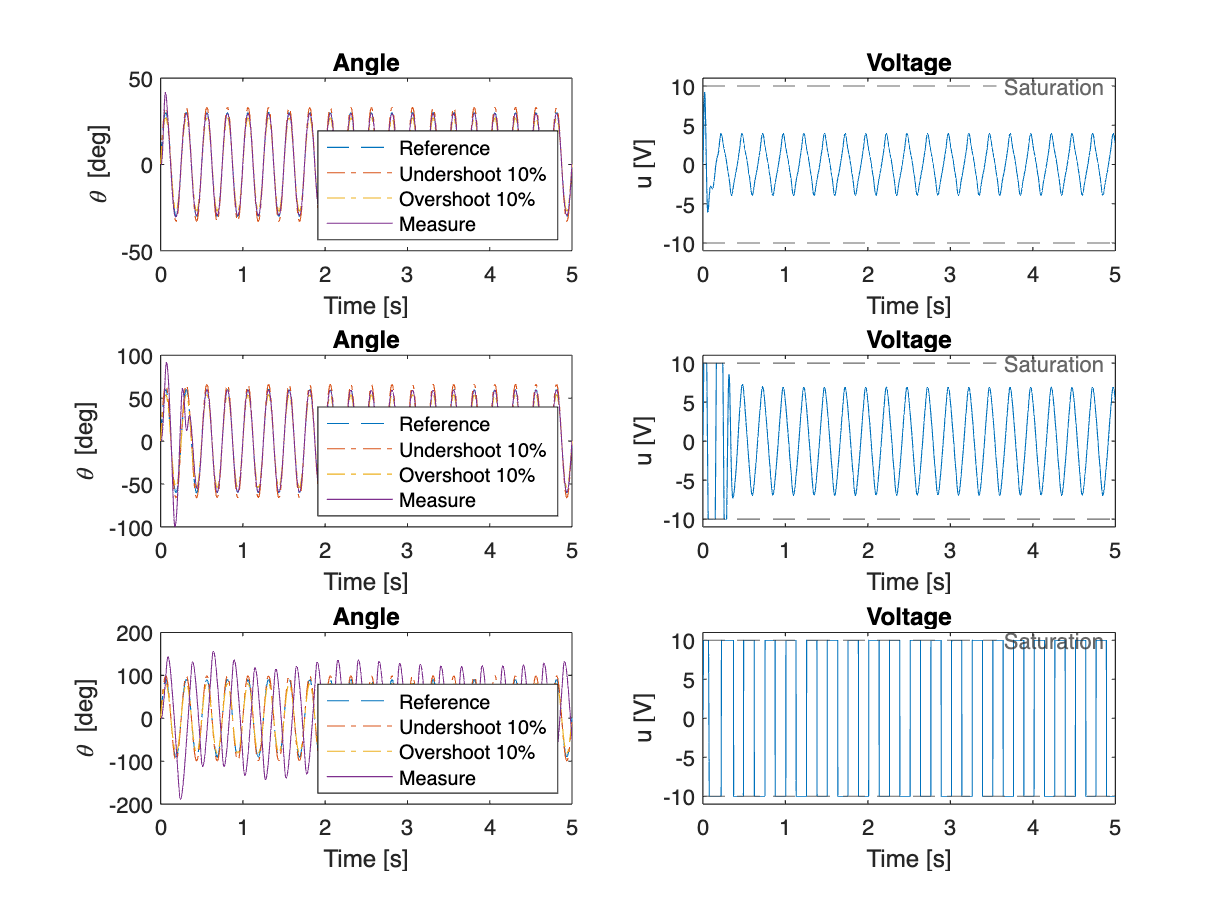

ssError.amp = 30;
ssObserver_simul.Tr2.amp30 =sim('lab1_extended_estimator','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');
ssError.amp = 60;
ssObserver_simul.Tr2.amp60 =sim('lab1_extended_estimator','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
ssError.amp = 90;
ssObserver_simul.Tr2.amp90 =sim('lab1_extended_estimator','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

figure("Name",'Results')
subplot(3,2,1)
plot(ssObserver_simul.Tr2.amp30.thref.time, ssObserver_simul.Tr2.amp30.thref.signals.values,'--');
hold on;
plot(ssObserver_simul.Tr2.amp30.thref.time, ssObserver_simul.Tr2.amp30.thref.signals.values*1.10,'-.');
plot(ssObserver_simul.Tr2.amp30.thref.time, ssObserver_simul.Tr2.amp30.thref.signals.values*0.9,'-.');
plot(ssObserver_simul.Tr2.amp30.thl_meas.time, ssObserver_simul.Tr2.amp30.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,2)
plot(ssObserver_simul.Tr2.amp30.u.time, ssObserver_simul.Tr2.amp30.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')


subplot(3,2,3)
plot(ssObserver_simul.Tr2.amp60.thref.time, ssObserver_simul.Tr2.amp60.thref.signals.values,'--');
hold on;
plot(ssObserver_simul.Tr2.amp60.thref.time, ssObserver_simul.Tr2.amp60.thref.signals.values*1.10,'-.');
plot(ssObserver_simul.Tr2.amp60.thref.time, ssObserver_simul.Tr2.amp60.thref.signals.values*0.9,'-.');
plot(ssObserver_simul.Tr2.amp60.thl_meas.time, ssObserver_simul.Tr2.amp60.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,4)
plot(ssObserver_simul.Tr2.amp60.u.time, ssObserver_simul.Tr2.amp60.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')


subplot(3,2,5)
plot(ssObserver_simul.Tr2.amp90.thref.time, ssObserver_simul.Tr2.amp90.thref.signals.values,'--');
hold on;
plot(ssObserver_simul.Tr2.amp90.thref.time, ssObserver_simul.Tr2.amp90.thref.signals.values*1.10,'-.');
plot(ssObserver_simul.Tr2.amp90.thref.time, ssObserver_simul.Tr2.amp90.thref.signals.values*0.9,'-.');
plot(ssObserver_simul.Tr2.amp90.thl_meas.time, ssObserver_simul.Tr2.amp90.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,6)
plot(ssObserver_simul.Tr2.amp90.u.time, ssObserver_simul.Tr2.amp90.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')

#### Observer for Trs = 0.5s

ssError.ridx = 3;
ssError.freq = ssError.wrs(ssError.ridx);
               
%% Settings of the correct poles for the estimator
ssEstimator.A_rho = [0 1 0; 0 0 1; 0 -ssError.wrs(ssError.ridx)^2 0];
ssEstimator.Ae = [ssEstimator.A_rho, zeros(3,2); ssP.B*ssEstimator.C_rho, ssP.A];
ssEstimator.Le = (place(ssEstimator.Ae', ssEstimator.Ce', ssEstimator.obspoles))'; % notice the last transpose
ssEstimator.Le

ans = 1.0e+06 *

    0.0125
    0.4680
    7.0499
    0.0002
    0.0225


SIMULATIONS

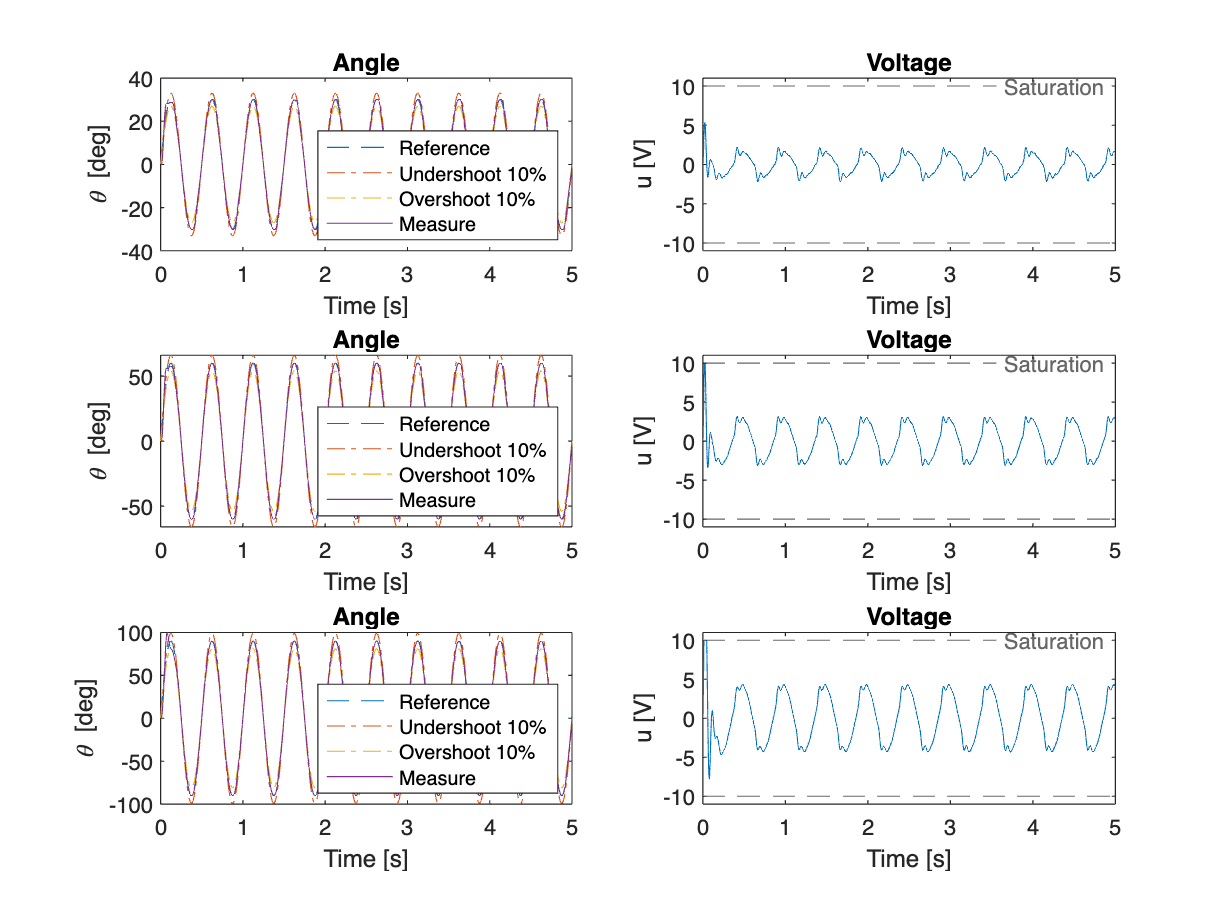

ssError.amp = 30;
ssObserver_simul.Tr3.amp30 =sim('lab1_extended_estimator','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');
ssError.amp = 60;
ssObserver_simul.Tr3.amp60 =sim('lab1_extended_estimator','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
ssError.amp = 90;
ssObserver_simul.Tr3.amp90 =sim('lab1_extended_estimator','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

figure("Name",'Results')
subplot(3,2,1)
plot(ssObserver_simul.Tr3.amp30.thref.time, ssObserver_simul.Tr3.amp30.thref.signals.values,'--');
hold on;
plot(ssObserver_simul.Tr3.amp30.thref.time, ssObserver_simul.Tr3.amp30.thref.signals.values*1.10,'-.');
plot(ssObserver_simul.Tr3.amp30.thref.time, ssObserver_simul.Tr3.amp30.thref.signals.values*0.9,'-.');
plot(ssObserver_simul.Tr3.amp30.thl_meas.time, ssObserver_simul.Tr3.amp30.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,2)
plot(ssObserver_simul.Tr3.amp30.u.time, ssObserver_simul.Tr3.amp30.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')


subplot(3,2,3)
plot(ssObserver_simul.Tr3.amp60.thref.time, ssObserver_simul.Tr3.amp60.thref.signals.values,'--');
hold on;
plot(ssObserver_simul.Tr3.amp60.thref.time, ssObserver_simul.Tr3.amp60.thref.signals.values*1.10,'-.');
plot(ssObserver_simul.Tr3.amp60.thref.time, ssObserver_simul.Tr3.amp60.thref.signals.values*0.9,'-.');
plot(ssObserver_simul.Tr3.amp60.thl_meas.time, ssObserver_simul.Tr3.amp60.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,4)
plot(ssObserver_simul.Tr3.amp60.u.time, ssObserver_simul.Tr3.amp60.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')


subplot(3,2,5)
plot(ssObserver_simul.Tr3.amp90.thref.time, ssObserver_simul.Tr3.amp90.thref.signals.values,'--');
hold on;
plot(ssObserver_simul.Tr3.amp90.thref.time, ssObserver_simul.Tr3.amp90.thref.signals.values*1.10,'-.');
plot(ssObserver_simul.Tr3.amp90.thref.time, ssObserver_simul.Tr3.amp90.thref.signals.values*0.9,'-.');
plot(ssObserver_simul.Tr3.amp90.thl_meas.time, ssObserver_simul.Tr3.amp90.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,6)
plot(ssObserver_simul.Tr3.amp90.u.time, ssObserver_simul.Tr3.amp90.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')

#### Observer for Trs = 1s

ssError.ridx = 4;
ssError.freq = ssError.wrs(ssError.ridx);
               
%% Settings of the correct poles for the estimator
ssEstimator.A_rho = [0 1 0; 0 0 1; 0 -ssError.wrs(ssError.ridx)^2 0];
ssEstimator.Ae = [ssEstimator.A_rho, zeros(3,2); ssP.B*ssEstimator.C_rho, ssP.A];
ssEstimator.Le = (place(ssEstimator.Ae', ssEstimator.Ce', ssEstimator.obspoles))'; % notice the last transpose
ssEstimator.Le

ans = 1.0e+06 *

    0.0127
    0.4902
    8.5209
    0.0002
    0.0227


SIMULATIONS

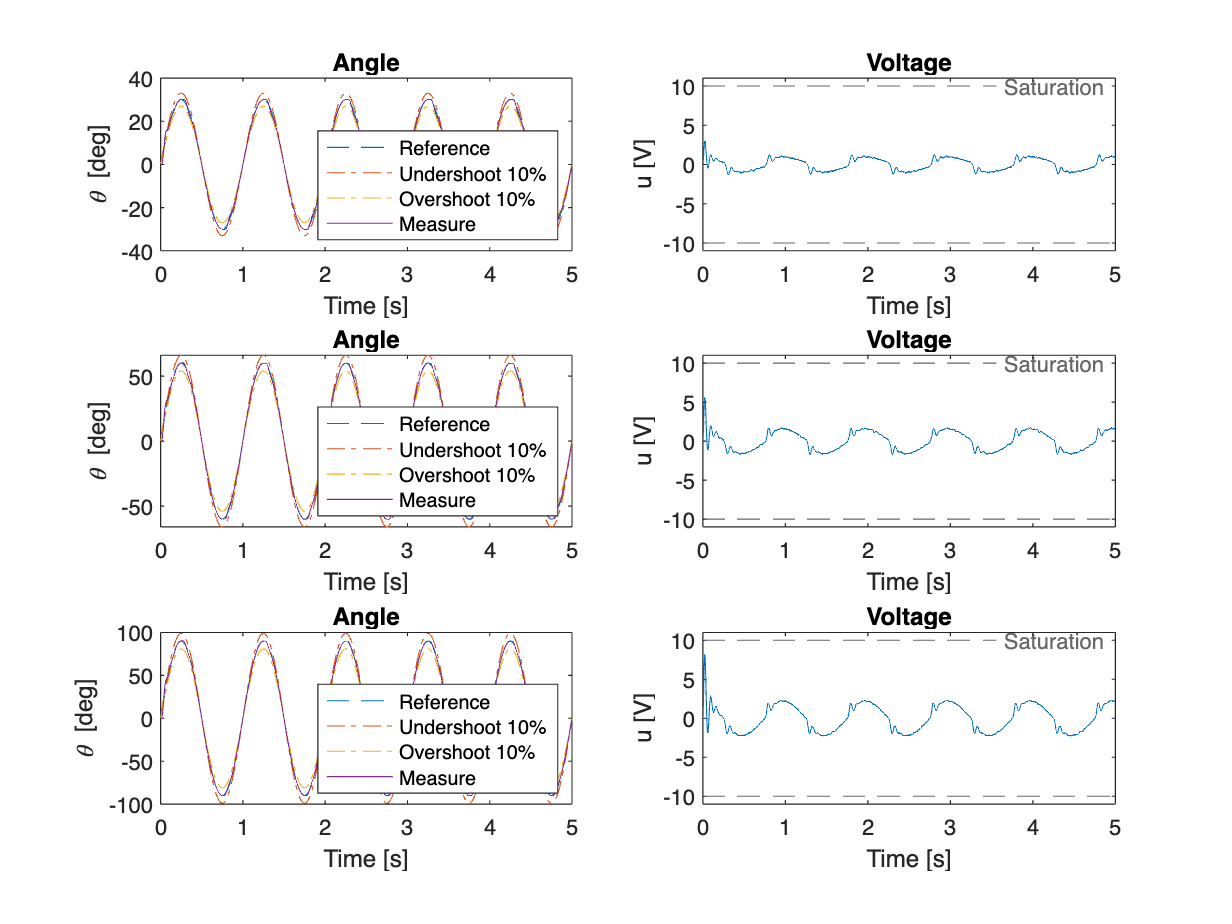

ssError.amp = 30;
ssObserver_simul.Tr4.amp30 =sim('lab1_extended_estimator','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');
ssError.amp = 60;
ssObserver_simul.Tr4.amp60 =sim('lab1_extended_estimator','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
ssError.amp = 90;
ssObserver_simul.Tr4.amp90 =sim('lab1_extended_estimator','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

figure("Name",'Results')
subplot(3,2,1)
plot(ssObserver_simul.Tr4.amp30.thref.time, ssObserver_simul.Tr4.amp30.thref.signals.values,'--');
hold on;
plot(ssObserver_simul.Tr4.amp30.thref.time, ssObserver_simul.Tr4.amp30.thref.signals.values*1.10,'-.');
plot(ssObserver_simul.Tr4.amp30.thref.time, ssObserver_simul.Tr4.amp30.thref.signals.values*0.9,'-.');
plot(ssObserver_simul.Tr4.amp30.thl_meas.time, ssObserver_simul.Tr4.amp30.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,2)
plot(ssObserver_simul.Tr4.amp30.u.time, ssObserver_simul.Tr4.amp30.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')


subplot(3,2,3)
plot(ssObserver_simul.Tr4.amp60.thref.time, ssObserver_simul.Tr4.amp60.thref.signals.values,'--');
hold on;
plot(ssObserver_simul.Tr4.amp60.thref.time, ssObserver_simul.Tr4.amp60.thref.signals.values*1.10,'-.');
plot(ssObserver_simul.Tr4.amp60.thref.time, ssObserver_simul.Tr4.amp60.thref.signals.values*0.9,'-.');
plot(ssObserver_simul.Tr4.amp60.thl_meas.time, ssObserver_simul.Tr4.amp60.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,4)
plot(ssObserver_simul.Tr4.amp60.u.time, ssObserver_simul.Tr4.amp60.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')


subplot(3,2,5)
plot(ssObserver_simul.Tr4.amp90.thref.time, ssObserver_simul.Tr4.amp90.thref.signals.values,'--');
hold on;
plot(ssObserver_simul.Tr4.amp90.thref.time, ssObserver_simul.Tr4.amp90.thref.signals.values*1.10,'-.');
plot(ssObserver_simul.Tr4.amp90.thref.time, ssObserver_simul.Tr4.amp90.thref.signals.values*0.9,'-.');
plot(ssObserver_simul.Tr4.amp90.thl_meas.time, ssObserver_simul.Tr4.amp90.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,6)
plot(ssObserver_simul.Tr4.amp90.u.time, ssObserver_simul.Tr4.amp90.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')

**[7 Estimator]** Repeat the test above of point 6 with a sinusoidal reference input of amplitude Ar = 40° and period Tr = 0.1 (but with the control designed to track a reference sinusoid with period Tr = 0.5 s). Compare the tracking error with that obtained in the previous case. 

The behaviuor of the plot is normal since we are using a controller design for a specific sinusoid frequency at a different frequency. In particular the controller works five times slower than the refernce.

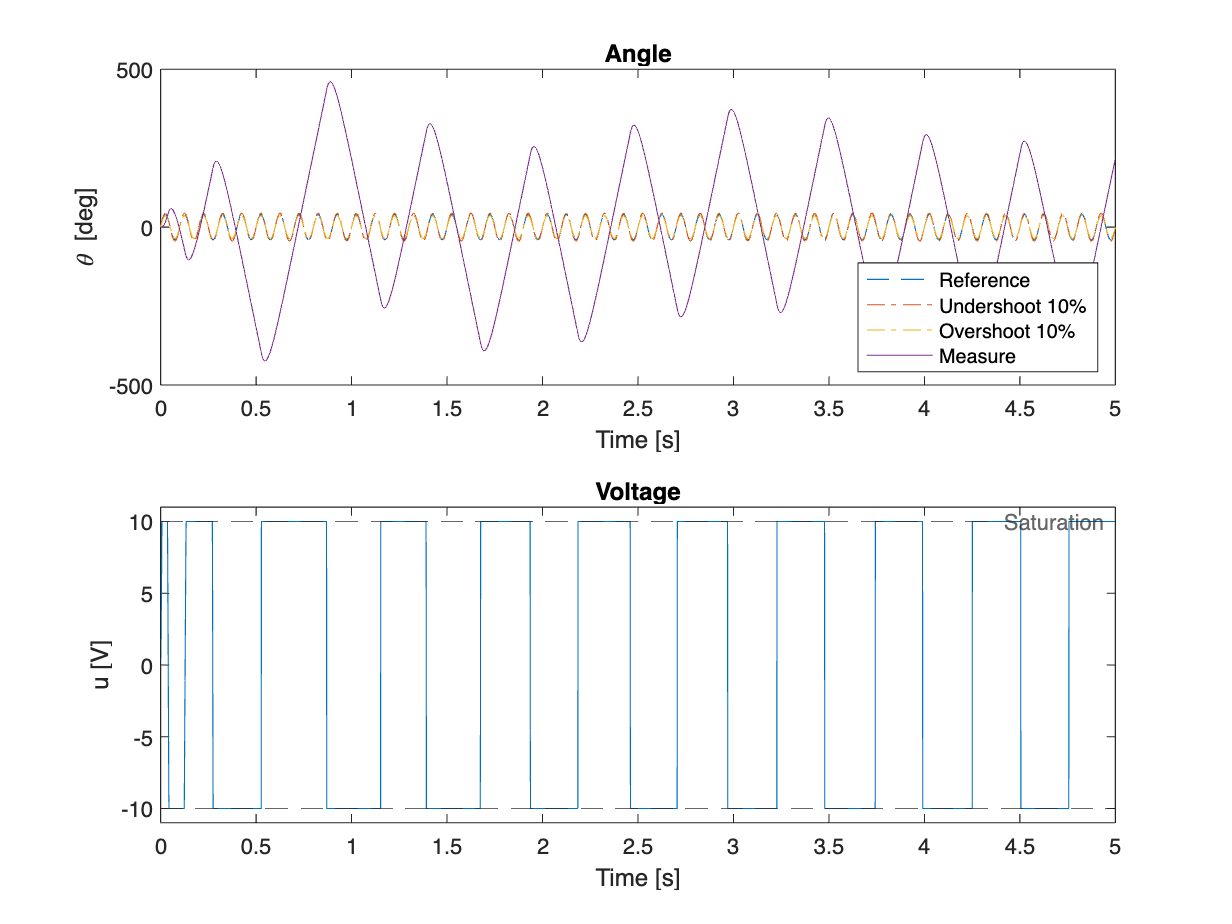

% Reference setting
ssError.ridx = 3;
               
%% Settings of the correct poles for the estimator
ssEstimator.A_rho = [0 1 0; 0 0 1; 0 -ssError.wrs(ssError.ridx)^2 0];
ssEstimator.Ae = [ssEstimator.A_rho, zeros(3,2); ssP.B*ssEstimator.C_rho, ssP.A];
ssEstimator.Le = (place(ssEstimator.Ae', ssEstimator.Ce', ssEstimator.obspoles))'; % notice the last transpose


ssError.amp =40;
% In this case we select a different frequency
ssError.freq = 2*pi./0.1;


ssObserver_simul.point_7 =sim('lab1_extended_estimator','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');

figure("Name",'Results')
subplot(2,1,1)
plot(ssObserver_simul.point_7.thref.time, ssObserver_simul.point_7.thref.signals.values,'--');
hold on;
plot(ssObserver_simul.point_7.thref.time, ssObserver_simul.point_7.thref.signals.values*1.10,'-.');
plot(ssObserver_simul.point_7.thref.time, ssObserver_simul.point_7.thref.signals.values*0.9,'-.');
plot(ssObserver_simul.point_7.thl_meas.time, ssObserver_simul.point_7.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(2,1,2)
plot(ssObserver_simul.point_7.u.time, ssObserver_simul.point_7.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')

**[( Estimator]** Repeat the test above of point 6 with a sinusoidal reference input of amplitude Ar = 40°

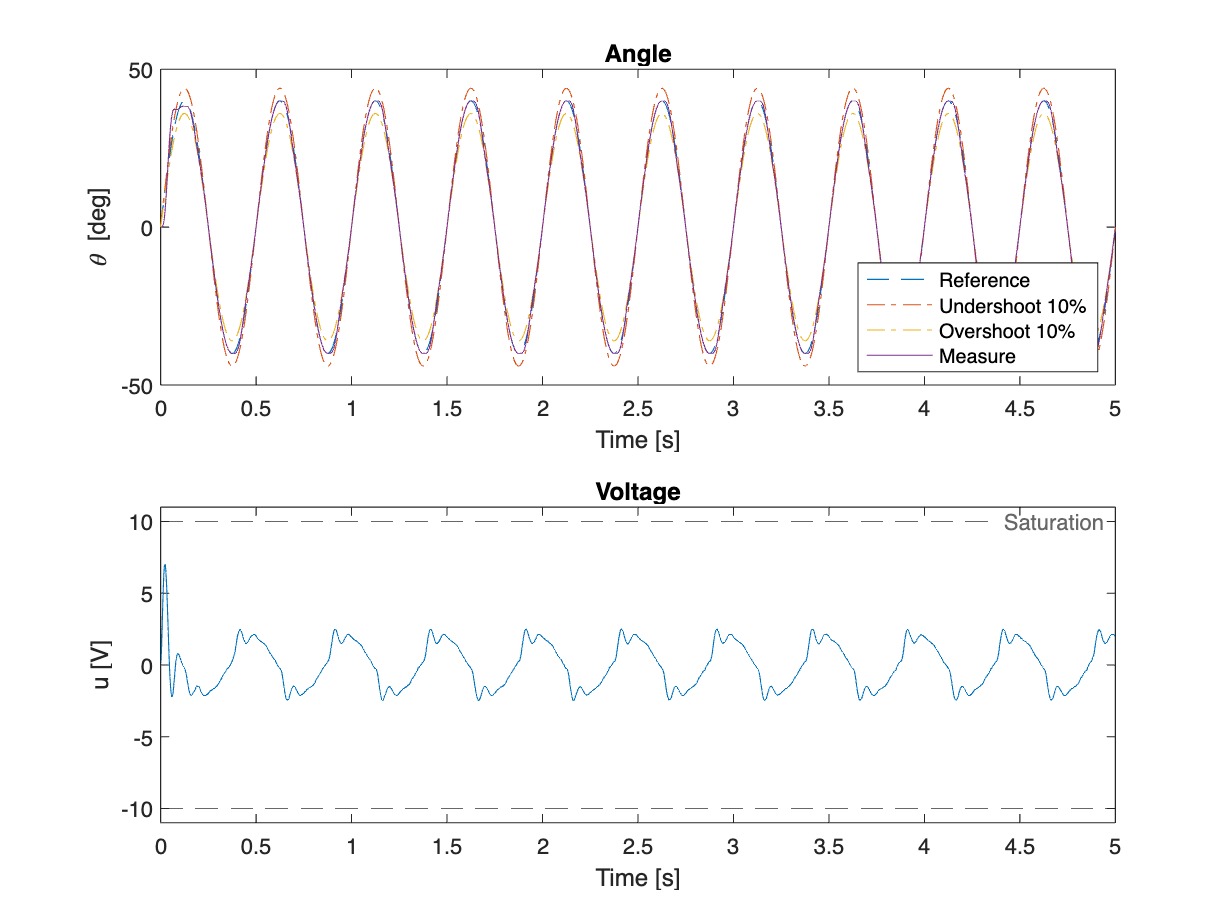

% Reference setting - invariate from point 7 apart from sine frequency
ssError.freq = ssError.wrs(ssError.ridx);

ssObserver_simul.point_8 =sim('lab1_extended_estimator','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');

figure("Name",'Results')
subplot(2,1,1)
plot(ssObserver_simul.point_8.thref.time, ssObserver_simul.point_8.thref.signals.values,'--');
hold on;
plot(ssObserver_simul.point_8.thref.time, ssObserver_simul.point_8.thref.signals.values*1.10,'-.');
plot(ssObserver_simul.point_8.thref.time, ssObserver_simul.point_8.thref.signals.values*0.9,'-.');
plot(ssObserver_simul.point_8.thl_meas.time, ssObserver_simul.point_8.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(2,1,2)
plot(ssObserver_simul.point_8.u.time, ssObserver_simul.point_8.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')

save('ssObserver_simul.mat','ssObserver_simul');